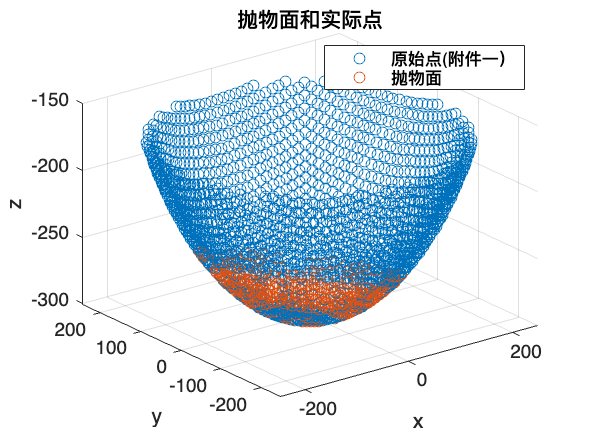

%此文件为问题二的检测
%依赖于rotate_of_plat 和plot_after_rotate
figure
Point_1 = readmatrix("附件1.csv");
Point_1(:,1) = [];
hold on
scatter3(Point_1(:,1),Point_1(:,2),Point_1(:,3))
len = size(Point_1,1);
for i = 1:len
    if n_plat*(Point_1(i,:)')+D>=0
        Point_1(i,:) = zeros(1,3);
    end
end

idx = find(sum(Point_1,2));
idx2 = find(~sum(Point_1,2));
result_point1 = Point_1(idx,:);
% scatter3(result_point1(:,1),result_point1(:,2),result_point1(:,3))
writematrix(result_point1,'附件1数据，径矢筛选后，直角坐标.xlsx')
% scatter3(eeee(:,1),eeee(:,2),eeee(:,3))
scatter3(e_temp(:,1),e_temp(:,2),e_temp(:,3))
writematrix(eeee,"理想抛物面上点的坐标.xlsx")
title('抛物面和实际点')
legend(["原始点(附件一）","抛物面"])
xlabel('x');
ylabel('y');
zlabel('z');
view(3)
grid on
hold off

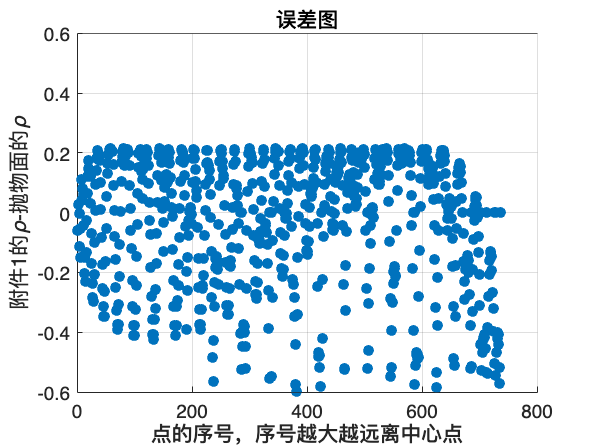

figure
[azimuth,elevation,r_point1] = cart2sph(result_point1(:,1),result_point1(:,2),result_point1(:,3));
new_data = [azimuth,elevation,r_point1];


